## **How to load and plot Neurostim data**

2020-12-14 -  Maureen Hagan <maureen.hagan@monash.edu>

Neurostim saves its data as objects, so it can be a little bit different if your'e used to normal matlab variables. The goal of this script is to walk you through an example, with some of the things you need to know about loading the data. This is by no means comprehensive, but will hopefully give you some intuition to get started on your own data. This script will walk through an example of loading and plotting up data from the "Salient Grid" task.

To complete this exercise, you'll need the marmo-lab repositories. See the wiki for a list of everything you need:

[https://github.com/SysNeuroHub/SysNeuroWiki/wiki/marmo-lab-neurostim](https://github.com/SysNeuroHub/SysNeuroWiki/wiki/marmo-lab-neurostim) 

The example data is all in this folder, so set your directory to where ever you've placed this.

Note: This data was collected on older versions of the repositories. Everything is now run on the 'master' branches, which should be what you're working on. When you load the data, you'll see lots of warnings about 'fixing backwards compatibility' - you can just ignore this warnings, this is why they're popping up. Everything should still run fine.

### Example Data

Just a brief background on the task so you understand what you're looking at in the rest of this file. The monkey's task is to fixate on a black and white donut for a variable duration (350-600 ms). Somewhere during that period, a grid of oriented bars would flash on around the donut for 200 ms. Sometimes, one of the bars would be orthagonal to the rest ('salient condition') and sometimes all the bars would be the same orientation ('non-salient condition'). 

The stimulus looks something like this:

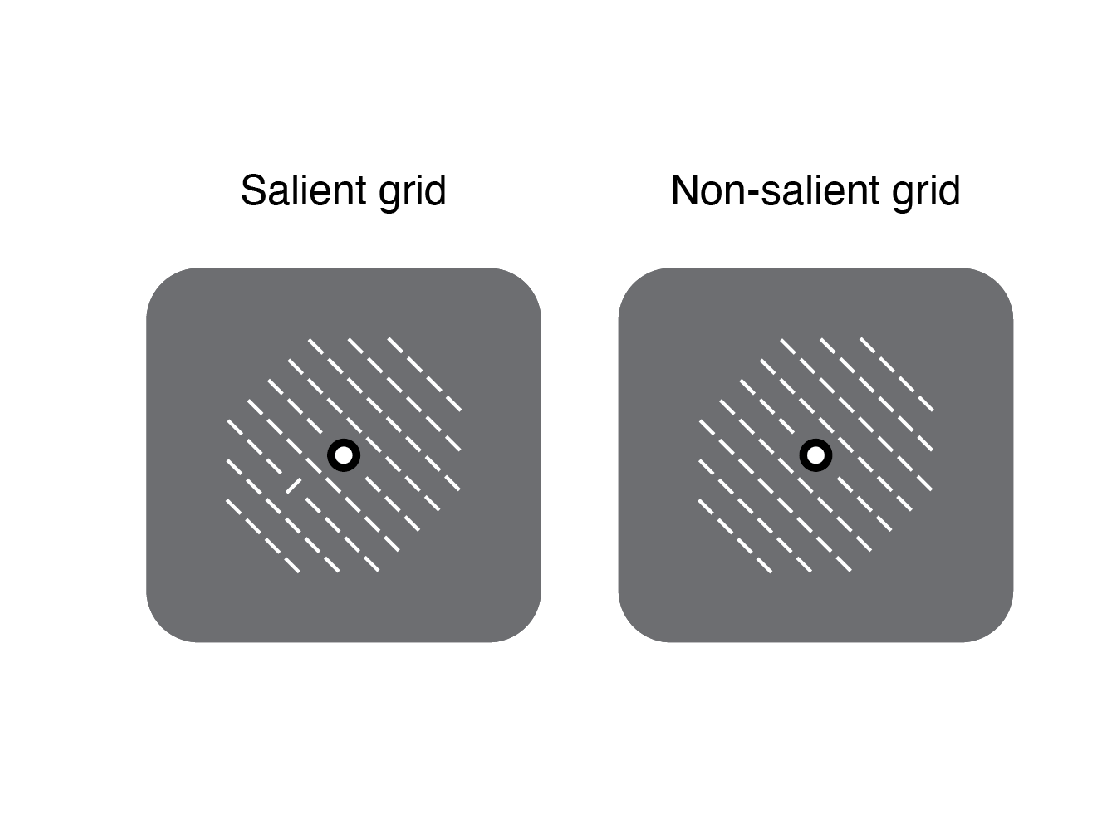

img = imread('salientgrid.png','Backgroundcolor',[1 1 1]);
figure;
image(img);
axis equal
axis off

The monkey's job was just to keep fixating. We're interested in whether cells change their tuning preferneces based on whether or not there was a salient 'target' in the grid.

### Behavior data files

Example data has been copied into this folder, but on the server you'll find data orgainzed by year/month/day. Within each day folder, you'll find all of the behavioral and neural files recorded on that day.

For behavioral data, there are two critical files that you'll need: the neurostim mat file and the eyelink file (-.edf) that contains all of the eye movement data.

The naming convention for these files is: 'monkeyname.taskname.time'

You should see these two files in this folder:

% eyelink file: m1898.salientgrid.095528.edf
% neurostim file: m1898.salientgrid.095528.mat 

#### Loading the Eyelink file

To load the edf file on its own, you need the edfmex file from Eyelink (see the wiki). Later, you'll see how you can get neurostim to do this step for you, but it can be useful to load the eye data on its own, especially if you're debugging something (ie the eye data coming out of neurostim doesn't look the way you think it should). Loading the eye data can be slow-ish, so you can skip this if you dont' need it right now.

eyedata = edfmex('m1898.salientgrid.095528.edf')

Loading:100%

eyedata = struct with fields:
       FSAMPLE: [1×1 struct]
        FEVENT: [1×14246 struct]
       IOEVENT: [1×6 struct]
    RECORDINGS: [1×2 struct]
        HEADER: '** DATE: Thu Mar  5 08:35:24 2020↵** TYPE: EDF_FILE BINARY EVENT SAMPLE TAGGED↵** VERSION: EYELINK II 1↵** SOURCE: EYELINK CL↵** EYELINK II CL v4.51 Mar 13 2010↵** CAMERA: EyeLink CL Version 1.4 Sensor=BJ9↵** SERIAL NUMBER: CL1-AAB06↵** CAMERA_CONFIG: AAB06140.SCD↵'
      FILENAME: 'm1898.salientgrid.095528.edf'


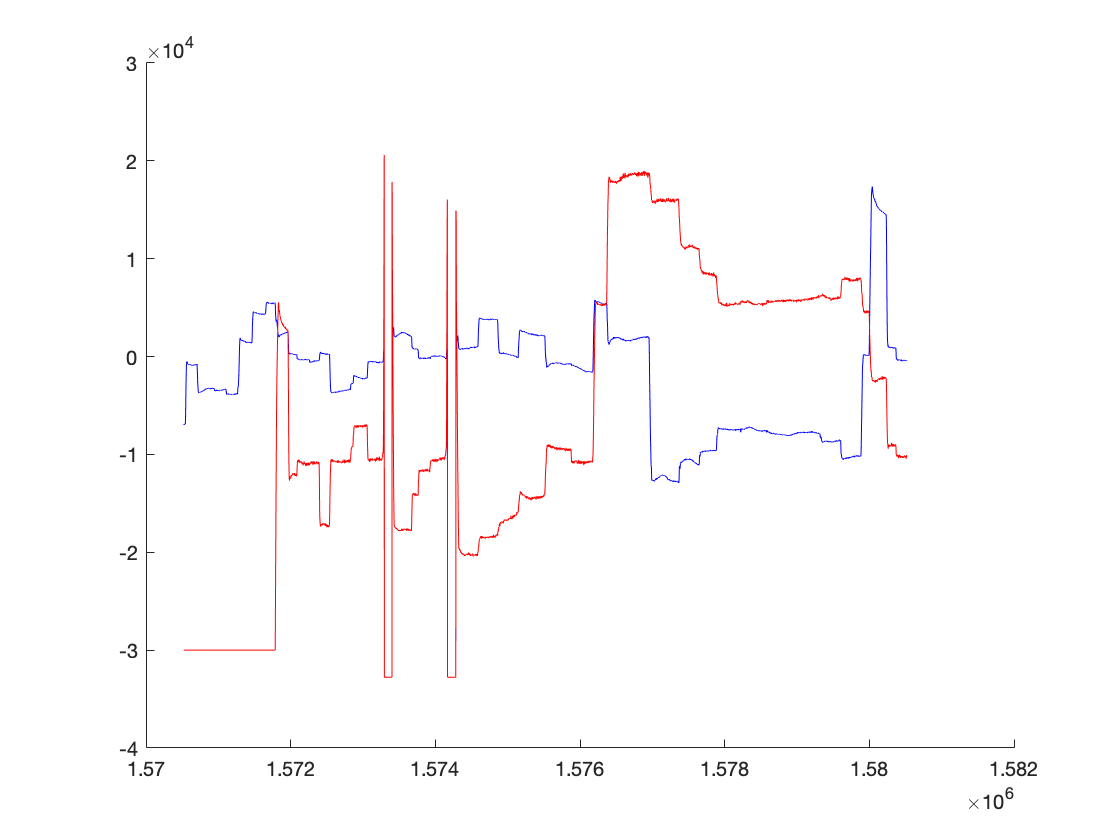

% data is in samples - sampling rate is 1000 samples/sec
% plot the x and y eye trace from the first 10e3 samples
samples = 1:10e3; % first 10 seconds of eye trace data
eyeNum = 2; % plot data from the right eye
figure; hold on;
plot(eyedata.FSAMPLE.time(samples),eyedata.FSAMPLE.px(eyeNum,samples),'-b') % horizontal eye position
plot(eyedata.FSAMPLE.time(samples),eyedata.FSAMPLE.py(eyeNum,samples),'-r') % vertical eye position

#### Loading the Stimulus file 

The neurostim file looks like a normal mat file, but if you try to just use matlab's load function, you'll find find that its a bit more complicated.

Try:

data = load('m1898.salientgrid.095528.mat')

Fixing backward compatibility of stored Neurostim object	 Not defined when saved (will get current default values) : gitTracker 
	 Not defined when saved (will get current default values) : messenger 
	 Not defined when saved (will get current default values) : seqNr 
	 Not defined when saved (will get current default values) : trialDynamicPrms 
	 Not defined currently (will be removed) : feedCache 
	 Not defined currently (will be removed) : feedCacheCntr 
	 Not defined currently (will be removed) : feedCacheWriteNow 


data = struct with fields:
    c: [1×1 neurostim.cic]


data.c

ans = CIC. Started at 09:55:28                                         
Stimuli: 5, Blocks: 500                                          
Conditions: 16, Trials: 20                                       
File: /home/marmolab/data/2020/03/05/m1898.salientgrid.095528.mat

You'll see the variable data is a structure with field 'c', and c containes the neuostim object 'cic'. To access the data in the object, we need to load it differently to a nomal mat file. 

To load the file, we need to load it as an object of the marmolab database:

d = marmodata.mdbase('m1898.salientgrid.095528.mat')

Fixing backward compatibility of stored Neurostim object	 Not defined when saved (will get current default values) : gitTracker 
	 Not defined when saved (will get current default values) : messenger 
	 Not defined when saved (will get current default values) : seqNr 
	 Not defined when saved (will get current default values) : trialDynamicPrms 
	 Not defined currently (will be removed) : feedCache 
	 Not defined currently (will be removed) : feedCacheCntr 
	 Not defined currently (will be removed) : feedCacheWriteNow 
Fixing backward compatibility of stored Neurostim object	 Not defined when saved (will get current default values) : gitTracker 
	 Not defined when saved (will get current default values) : messenger 
	 Not defined when saved (will get current default values) : seqNr 
	 Not defined when saved (will get current default values) : trialDynamicPrms 
	 Not defined currently (will be removed) : feedCache 
	 Not defined currently (will be removed) : feedCacheCntr 
	 Not defined

d =   mdbase with properties:

             file: {'/Users/mhagan/Documents/MATLAB/matlab_live_scripts/how_to_analyze_neurostim_data/m1898.salientgrid.095528.mat'}
          datenum: 7.3786e+05
           format: 'NSD'
          subject: 'm1898'
         paradigm: 'salientgrid'
             eyem: [0×0 struct]
              eye: [0×0 marmodata.eye]
              lfp: [0×0 marmodata.cdata]
             muae: [0×0 marmodata.cdata]
           spikes: [0×0 marmodata.sdata]
      lfpSettings: [1×1 struct]
     muaeSettings: [1×1 struct]
    spikeSettings: [1×1 struct]
             meta: [1×1 marmodata.meta]
             path: {'/Users/mhagan/Documents/MATLAB/matlab_live_scripts/how_to_analyze_neurostim_data'}
             date: '2020-03-05'
             time: '09:55:28'
           pooled: 0
         numConds: 16
          condIds: [1×606 double]
        numTrials: 606


Now you can see 'd' looks more like a familiar structure variable with different fields like the filename, subject name, paradigm. You'll notice fields like 'eye', 'spike' and 'lfp' are empty - this is because we havent told it to load data from these files (more on that below). But you can see in this example, the data has 606 trials, with 16 different conditions. Different tasks may have different task information here.

Only two parameters are varied in this task, the target orientation and the orientaiton of the distractors (if target orientaiton == distractor orientaiton, then its a non-salient trial). These parameters are saved in the 'd.meta' under the stimulus name (which is 'origrid') as 'torientaiton' and 'dorientation'. This is not so obvious just looking at the 'd' variable - you have to know a little bit about you task (reading the stimulus file will help).

But we can use this to pull out the orietnation for the first 10 trials: 

targets = d.meta.origrid.torientation('time',Inf).data; % orientation of the salient target
distractors = d.meta.origrid.dorientation('time',Inf).data; % orietation of the distractors

% orietnation of targets on first 10 trials
target_orietnation = targets(1:10)'

target_orietnation =     22    22   232   172    22    82   112   112   202    22


% orientaiton of distractors on first 10 trials
distractor_orientation = distractors(1:10)'

distractor_orientation =    112   112   232   262    22   172   202   112   202    22


% which of the first 10 trials were 'salient'?
salient_trials = target_orietnation ~= distractor_orientation

salient_trials = 1×10 logical array
   1   1   0   1   0   1   1   0   0   0


### **The stimulus analysis file**

To make this process easier, we create an analysis file for each stimulus. This analysis file has built in functions to pull out the relevant parts of the data. The analysis files live in the 'marmo-lab-stimuli' repository. Each class of task has an '+analysis' folder, which should have a file that matches the name of the task. 

So first, let's load the data again, and this time we'll get Neurostim to load the eye movement data as well. The advantage of gettting Neurostim to load the eye movement data is that it will do a bit of pre-processing for us. When we loaded the edf file on its own, the data was all in samples. Neurostim will break up the samples by trial and convert from samples to time so that the eye, neural, and behavioral data are all aligned for us.

d = marmodata.mdbase('m1898.salientgrid.095528.mat','loadArgs',{'loadEye',true}); % load neurostim and eye movement data

Fixing backward compatibility of stored Neurostim object	 Not defined when saved (will get current default values) : gitTracker 
	 Not defined when saved (will get current default values) : messenger 
	 Not defined when saved (will get current default values) : seqNr 
	 Not defined when saved (will get current default values) : trialDynamicPrms 
	 Not defined currently (will be removed) : feedCache 
	 Not defined currently (will be removed) : feedCacheCntr 
	 Not defined currently (will be removed) : feedCacheWriteNow 
Fixing backward compatibility of stored Neurostim object	 Not defined when saved (will get current default values) : gitTracker 
	 Not defined when saved (will get current default values) : messenger 
	 Not defined when saved (will get current default values) : seqNr 
	 Not defined when saved (will get current default values) : trialDynamicPrms 
	 Not defined currently (will be removed) : feedCache 
	 Not defined currently (will be removed) : feedCacheCntr 
	 Not defined

100%

% eye data can take a little while to load, you should see a little
% progress note priting up to 100%

Now you should see that d.eye is not empty, and has eye movement data for each trial!

The analysis file for this task is:

% ~/marmolab_stimuli/+salientgrid/+analysis/salientgrid.m

Its worth opening it up and reading through it to see examples of what you can do with this data. The analysis files are class definition or 'classdef' files for the task object. 

Why do we do this? One way to think of it, if you're familiar with matlab and structure variables, you'll know that structure variables are a handy way of organizing all your data. Each class def file has a 'methods' section that contains the fucntions for analyzing the data. Basically, this allows you to organize your analysis in a structure-like format - so you're applying the same orgaizational skills to your analysis as you would your data. 

So let's pull up the target and distractor orietations like we did above, but this time we can just use the functions already in the methods section:

% first let's load up the analysis classdef
dd = salientgrid.analysis.salientgrid(d);

@salientgrid.salientgrid(): nargin = 1.



% now we can use the functions in the analysis file. There are two
% different syntaxes you can use to do this:
target_orientation = dd.gettOrientation(); 
% or like this (get the distractors):
distractor_orientation = getdOrientation(dd);

% hopefully it gives us the same data as before:

% orietnation of targets on first 10 trials
target_orientation(1:10)'

ans =     22    22   232   172    22    82   112   112   202    22


% orientaiton of distractors on first 10 trials
distractor_orientation(1:10)'

ans =    112   112   232   262    22   172   202   112   202    22


% which of the first 10 trials were 'salient'?
salient_trials = target_orientation(1:10)' ~= distractor_orientation(1:10)'

salient_trials = 1×10 logical array
   1   1   0   1   0   1   1   0   0   0



% easier, right?

Some of the functions allow for additional inputs, such as trial IDs, if you want data from a specific set of trials. For example, say we wanted the fixation durations (how long the monkey fixated on each trial) for only the salient trials (where the target orientation and distractor orientaiton don't match):

% we can use the variables from above to get the trial IDs for the salient
% trails:
salient_trials = find(target_orientation ~= distractor_orientation);

% and get the fixation durations for only the salient trials:
salient_fix_durs = getFixationDuration(dd,salient_trials);

% this should be roughly half the trials (total trials = 606):
size(salient_fix_durs) % yep!

ans =    302     1


#### **Plotting data!**

For figures that you're going to plot frequently/for each recording session, like behavior summaries or orietnation tuning, its worth adding some plot functions. In this analysis file, there are a couple of plot functions, one for behavior and one for orientation tuning. For this task, the things we want to see are the eye traces for the fixations on each trial and distributions of the fixation durations.

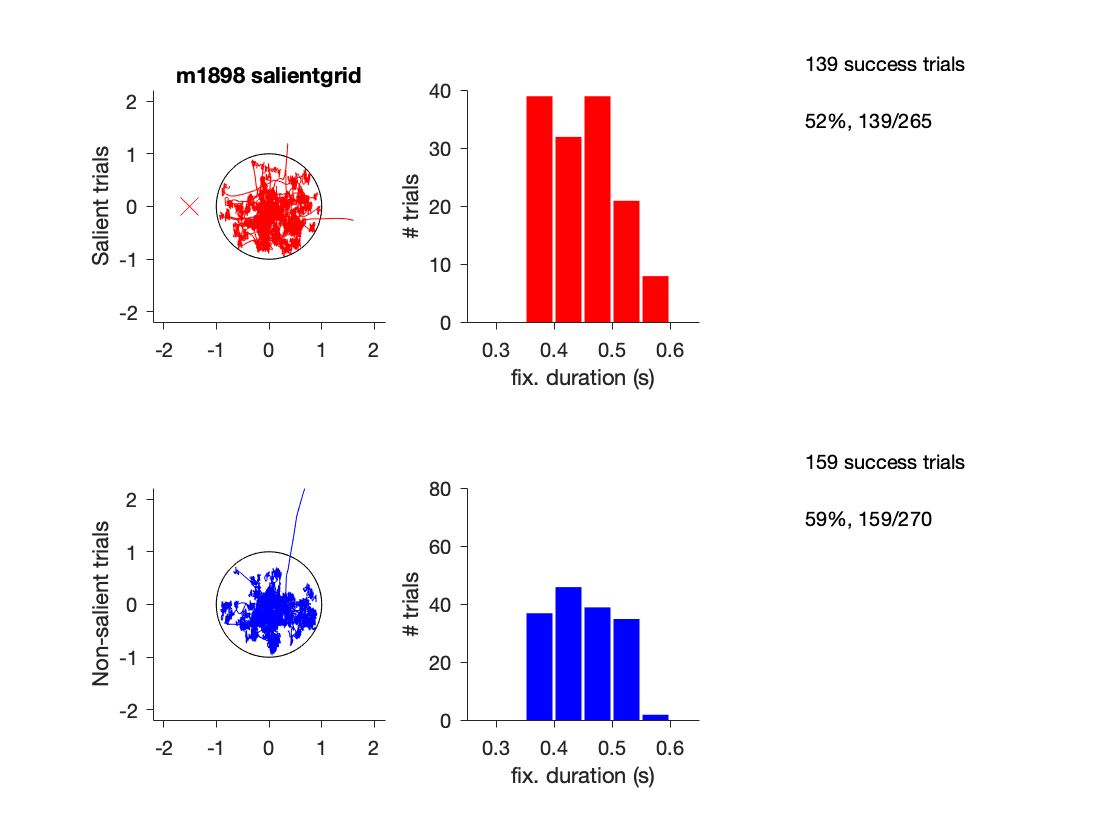

% plot summary of behavioral data
dd.plotBehavior();

So here the 'x' shows where the target was on salient trials, the black circles show the limits for the fixation window, and the histogram shows the successful trials at each fixation duration. So we can see this guy struggles a bit with longer fixation durations, but overall is completing roughly half of trials, and does as well as on salient trials and non-salient trials. 

### Neural data files

For the neural data, currently all of the data is collected using openEphys data acquisistion software. In addtion to the behavioral files, each day where a neural recording was made should have a folder with a name that matches the name of the neurostim mat file. This file will contain all of the raw data collected on the day, as well as any pre-processed data. You can put 'channels' as an input arguement to load specific channels.

To load spiking data, we currently have a few choices. From the raw data we can load multiunit data that has been simply thresholded, a multiunit evenelope, and spike-sorted data via kilosort (if kilosort has been run on that day).

The ephys data files are too big for this repostiory, so the code below won't actually run. But here is an example of how you would load some multiunit data:

% loading multiunit spiking data from (ghetto method)

d = marmodata.mdbase('m1898.salientgrid.095528.mat','loadArgs',{'spikes',true,'source','ghetto','reload',false}) % load multiunit spiking data

% other useful inputs:
%'source' - what type of spiking data you want
%   'ghetto' refers to simple, multiunit spike thresholds
%   can also be followed by 'kilo' if kilo sort has been run
%'channels' - followed by an array or single number to specify what
%channel(s) you want

This can now be used with any spiking functions in the ananlysis file.